# 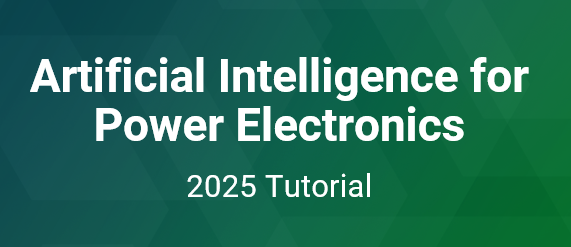

# **Autoencoder Neural Network (Deep Learning) for Auto-association **

### Demo 3: The objective is to demonstrate the application of an autoencoder neural network to estimate voltage sensor readings and predict potential sensor malfunctions.

# 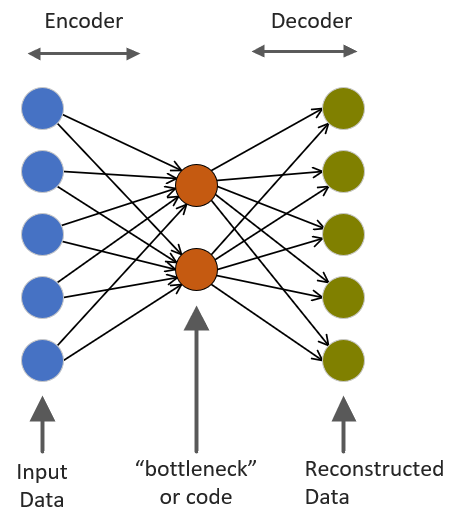

Figure 1: Generic autoencoder NN representation.

The autoencoder is a type of neural network that consists of an encoder and a decoder. It is trained to replicate its input at the output, with the encoder mapping the input to a hidden representation, while the decoder attempts to map this hidden representation back to the original input data. 

A key feature of the autoencoder is the 'bottleneck' — a compressed representation of the input data. By forcing this compression, the autoencoder can learn correlations within the data, allowing it to capture existing relationships.

## **1º step: Create a function to generate data for training your ANN**

Create a matrix called 'V' with 5 rows (one for each sensor) and 1000 columns, representing the observations. 

In this example, assume that all the sources vary simultaneously with the same shift. 

Additionally, limit the maximum voltage value to 50V and the minimum voltage value to 30V.

clear variables

Vmin = 30;   % min voltage value that the source can assume
Vmax = 50;   % max voltage value that the source can assume
no = 1000;   % number of observations

% ------- CREATE YOUR DATA ---------------------------------

% Example ---------------------------------------
V1 = round(Vmin + (Vmax-Vmin) .* rand(no,1),1);

figure;
plot(V1)
xlim([0 no]), ylim([Vmin Vmax])
xlabel('Samples'), ylabel('Voltage')

V2 = V1;                % all the source varies equally
V3 = V1;
V4 = V1;
V5 = V1;

V = [V1 V2 V3 V4 V5]';  % 5x1000 data set
% ------------------------------------------------


## **2º step: Split data**

Before training, let's separate part of the generated data to test the performance of the neural network after it is trained.

SplitRatio = 0.8;
% Create a random permutation of indices
ind = crossvalind('HoldOut', size(V, 2), SplitRatio);
 
% Use the indices to split the data into training and testing sets
V_train = V(:,ind == 0);
V_test = V(:,ind == 1);

## **3º step: **Neural Network configuration

Using the following code, you can define a set of parameters and train your autoencoder neural network. 

You can explore these parameters to optimize the training of the neural network. 

Use the training dataset (V_train from the previous step)

% Autoencoder NN
% *use rng for reproducibility, for example: rng(0,'twister')

hiddenSize = 2;     % Number of neurons in the code layer

% Autoencoder parameters
autoNN = trainAutoencoder(V_train,hiddenSize,...
        'EncoderTransferFunction','satlin',...       % activation function for encoder layer
        'DecoderTransferFunction','purelin',...      % activation function for decoder layer
        'L2WeightRegularization',0.01,...
        'SparsityRegularization',2,...
        'SparsityProportion',0.20);


**Autoencoder Parameters:**

- **Encoder and Decoder Transfer Function:** Activation function (e.g., 'logsig', 'satlim', 'purelim').

- **Maximum Number of Iterations (Epochs):** Example: `'MaxEpochs', 300`.

- **L2 Weight Regularization and Sparsity Regularization:** These are parameters of the cost function used during training.

- **Sparsity Proportion:** A parameter of Sparsity Regularization that specifies the desired proportion of training examples a neuron should respond to.

- **Training Algorithm:** Example: `'trainscg'` (default).

*You can access the MATLAB Help or Documentation for more details on the parameters of the autoencoder neural network.*

## **4º step: Analyze the performance **

Use the test dataset (V_test from step 2) to evaluate the neural network's performance by comparing its output with the target values.

V_Reconstructed = predict(autoNN,V_test);
figure;
plot(V_test,'ro');                  % target values
hold on
plot(V_Reconstructed,'b*');         % estimated values
hold off
MSE = mse(V_test-V_Reconstructed)   % mean of squared errors


## **5º step**: Deploy the neural network to Simulink 

Create a block for your trained neural network in the Simulink environment.

net = network(autoNN)   % convert the autoencoder object into network object 
gensim(net)             % export to Simulink

## **6º step**: Open the model to test your NN

Open the complete model for Demo 3. 

Once the model opens, copy and paste the neural network into the main model in the marked area. 

The inputs to the neural network are the voltage measurements.

open('demo3_model')
Vdc = 38;               % initial value of the DC sources


## **7º step**: Simulate the model

Now, click the 'Run' button to allow your neural network to estimate the voltage readings. 

You can check the display to compare the NN output with the actual values read from the sensors. 

## **8º step**: Apply a drift to sensor 1 and use the NN to validate the measurements

Simulate a drift in the measurements of sensor 1 by using the switch to define the drift. 

Then, compare the NN output with the sensor's measurement.

## **Instructor Team:**

Joao O. P. Pinto   – Oak Ridge National Laboratory – Knoxville, pintoj@ornl.gov 

Burak Ozpineci    –  Oak Ridge National Laboratory – Knoxville, burak@ornl.gov

Marcio Kimpara   – Oak Ridge National Laboratory – Knoxville, magrikimparm@ornl.gov

Pedro Ribeiro      –  Oak Ridge National Laboratory – Knoxville, ribeirope@ornl.gov

Renata Kimpara  –  Oak Ridge National Laboratory – Knoxville, rezendedacor@ornl.gov

Feel free to contact us.